# Section 1: Identification

## 1.1 Run simulation to generate identification data

cd(fileparts(matlab.desktop.editor.getActiveFilename))
addpath(genpath('./utils'))
ini; % Run initialization file ini.m
rng(2026) 

mdl_name="model";
data_dir="./data/";
fname=data_dir+"identification"+".mat";

% Time
Ts=T_s; Tend=31; % Generate a 31-second trajectory 
Tss=(0:Ts:Tend).';
Ctr_mode=[0,1;Tend+1,1]; 
pGFM.ctrl.mode=Ctr_mode; pGFL.ctrl.mode=Ctr_mode;

% PMU Measurement setting
pmu=pGFM.pmu;
pmu.dT=1e-4;
pmu.Anos=1e-3*[V_b,V_b,V_b,I_b,I_b,I_b];
pmu.seed=1234;
pGFM.pmu=pmu; pGFL.pmu=pmu;

% GFM parameters
p1=pGFM;
p1.gfm_type="droop";
p1.FPdroop=5e-2; % f-P droop slope: f/P (pu)
p1.VQdroop=2e-2; % V-Q droop slope: V/Q (pu)
p1.wc=5*2*pi;

p3=pGFM;
p3.gfm_type="vsg";
p3.Dp=0.14;
p3.J=0.045;
p3.VQdroop=2e-2;

p1=update_pIBR(p1); p3=update_pIBR(p3);

% GFL parameters
pGFL.FPdroop=5e-2; 
pGFL.VQdroop=5e-2; 
p2=pGFL; p4=pGFL;

p2=update_pIBR(p2); p4=update_pIBR(p4);

*Small* load perturbation ($\pm
$1% p.u.) and set-point excitation ($\pm$1% p.u.)

% Excitation amplitudes 
Load.A=1e-2;
Ps.A=1e-2; Qs.A=1e-2; ws.A=0; Vs.A=1e-2;

**No** *large* disturbance: dPload & dQload are 0

TPload=5; dPload=0*S_b;
TQload=7; dQload=0*S_b;

Function traj() generates bounded, random, but continuous trajectories

% Load perturbations
parm.type='sin'; parm.N=20; parm.w=20*2*pi;
DynLoad_Ps=S_b*traj(Tss,parm,Load.A,0,1);
DynLoad_Qs=S_b*sqrt(1-PF^2)*traj(Tss,parm,Load.A,0,1);
DynLoad_Ps=DynLoad_Ps+step(Tss,TPload,dPload);
DynLoad_Qs=DynLoad_Qs+step(Tss,TQload,dQload);

% Inverter excitation commands
nIBR=4;
parm.type='sin'; parm.N=60; parm.w=50*2*pi;
SecCtrs_Ps=S_b*traj(Tss,parm,Ps.A,0.5,nIBR);
SecCtrs_Qs=S_b*traj(Tss,parm,Qs.A,sqrt(1-PF^2),nIBR);
SecCtrs_ws=w_b*traj(Tss,parm,ws.A,1,nIBR);
SecCtrs_Vs=V_m*traj(Tss,parm,Vs.A,1,nIBR);

p1.ctrl.excit=[Tss,SecCtrs_Ps(:,1),SecCtrs_ws(:,1),SecCtrs_Qs(:,1),SecCtrs_Vs(:,1)];
p2.ctrl.excit=[Tss,SecCtrs_Ps(:,2),SecCtrs_ws(:,2),SecCtrs_Qs(:,2),SecCtrs_Vs(:,2)];
p3.ctrl.excit=[Tss,SecCtrs_Ps(:,3),SecCtrs_ws(:,3),SecCtrs_Qs(:,3),SecCtrs_Vs(:,3)];
p4.ctrl.excit=[Tss,SecCtrs_Ps(:,4),SecCtrs_ws(:,4),SecCtrs_Qs(:,4),SecCtrs_Vs(:,4)];

% Measurement-noise seeds follow the rng setting above.
p1.pmu.seed=ceil(1e4*rand); p3.pmu.seed=ceil(1e4*rand);
p2.pmu.seed=ceil(1e4*rand); p4.pmu.seed=ceil(1e4*rand);


Run

tic
[~,sim_out]=evalc("sim(mdl_name,'SimulationMode','rapid-accelerator'," + ...
    "'StopTime',num2str(Tend),'ReturnWorkspaceOutputs','on')");
toc
% Collect the existing m1-m4 output buses
clear YU
t=(T_island+0.1:pmu.dT:Tend).';
YU.t=t;
YU.m1=curtail(sim_out.logsout.getElement('m1').Values,t); YU.m1.t=t; YU.m1.pIBR=p1;
YU.m2=curtail(sim_out.logsout.getElement('m2').Values,t); YU.m2.t=t; YU.m2.pIBR=p2;
YU.m3=curtail(sim_out.logsout.getElement('m3').Values,t); YU.m3.t=t; YU.m3.pIBR=p3;
YU.m4=curtail(sim_out.logsout.getElement('m4').Values,t); YU.m4.t=t; YU.m4.pIBR=p4;
if ~isfolder(data_dir), mkdir(data_dir); end
save(fname,'YU','-v7.3');

## 1.2 Identify IBR parameters using EPC-SINDy

load('./data/identification.mat','YU');
T_ident=[1,31];

m1, ..., m4 are *noisy* PMU measurements

[m1,p1]=extract_measurements(YU.m1,T_ident);
[m2,p2]=extract_measurements(YU.m2,T_ident);
[m3,p3]=extract_measurements(YU.m3,T_ident);
[m4,p4]=extract_measurements(YU.m4,T_ident);

Use only *noisy* PMU measurements for identification

p1_hat=identification(m1); p2_hat=identification(m2);
p3_hat=identification(m3); p4_hat=identification(m4);

p1.tmpc.pIBR=p1_hat;p2.tmpc.pIBR=p2_hat;
p3.tmpc.pIBR=p3_hat;p4.tmpc.pIBR=p4_hat;

*Update* tube-MPC parameters with identified IBR parameters

p1=update_pIBR(p1);p2=update_pIBR(p2);
p3=update_pIBR(p3);p4=update_pIBR(p4);

**Visualization**

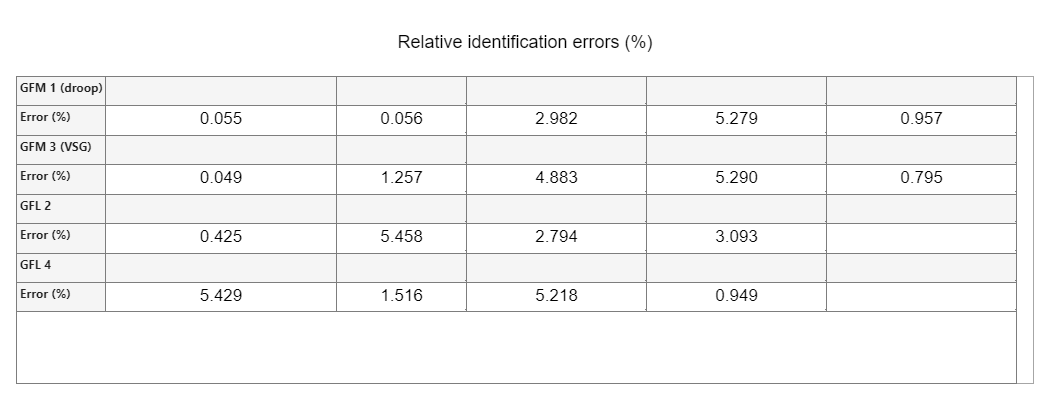

% GFM relative errors (%)
actualGFM=[p1.kfp,p1.kvq,p1.Kpi.v/p1.RLC(3),p1.wc;
           p3.kfp,p3.kvq,p3.Kpi.v/p3.RLC(3),p3.wc];
estimatedGFM=[p1_hat.kfp,p1_hat.kvq,p1_hat.Kpv,p1_hat.Kiv,p1_hat.wc;
              p3_hat.kfp,p3_hat.kvq,p3_hat.Kpv,p3_hat.Kiv,p3_hat.wc];
errorGFM=100*abs(estimatedGFM./actualGFM-1);

% VSG damping and inertia from the same GFM fit.
Dp3_hat=1/(p3.w_b*p3_hat.kfp);
J3_hat=Dp3_hat/p3_hat.wc;
actualVSG=[p3.Dp,p3.kvq,p3.Kpi.v/p3.RLC(3),p3.J];
estimatedVSG=[Dp3_hat,p3_hat.kvq,p3_hat.Kpv,p3_hat.Kiv,J3_hat];
errorVSG=100*abs(estimatedVSG./actualVSG-1);

% GFL relative errors (%)
actualGFL=[p2.kfp,p2.kvq,p2.Kpi.p*p2.I_b/p2.S_b/p2.tau;
           p4.kfp,p4.kvq,p4.Kpi.p*p4.I_b/p4.S_b/p4.tau];
estimatedGFL=[p2_hat.kfp,p2_hat.kvq,p2_hat.Kp/p2_hat.tau,p2_hat.Ki/p2_hat.tau;
              p4_hat.kfp,p4_hat.kvq,p4_hat.Kp/p4_hat.tau,p4_hat.Ki/p4_hat.tau];
errorGFL=100*abs(estimatedGFL./actualGFL-1);

% Identification error table
comparison=["$\sigma_{\omega,1}$","$\sigma_{v,1}$","$K^p_{v,1}/C_{f,1}$","$K^i_{v,1}/C_{f,1}$","$\omega_1^{\mathrm{c}}$";
            compose("%.3f",errorGFM(1,:));
            "$D_{p,3}$","$\sigma_{v,3}$","$K^p_{v,3}/C_{f,3}$","$K^i_{v,3}/C_{f,3}$","$J_3$";
            compose("%.3f",errorVSG);
            "$\sigma_{\omega,2}$","$\sigma_{v,2}$","$K^p_{p,2}/\tau_2$","$K^i_{p,2}/\tau_2$","";
            compose("%.3f",errorGFL(1,:)),"";
            "$\sigma_{\omega,4}$","$\sigma_{v,4}$","$K^p_{p,4}/\tau_4$","$K^i_{p,4}/\tau_4$","";
            compose("%.3f",errorGFL(2,:)),""];
% Fit LaTeX symbols within the table rows.
mathCells=startsWith(comparison,"$");
comparison(mathCells)=insertAfter(comparison(mathCells),1,"\scriptstyle ");
tableIdentification=array2table(comparison, ...
    'RowNames',{'GFM 1 (droop)','GFM 1 error (%)','GFM 3 (VSG)','GFM 3 error (%)', ...
                'GFL 2','GFL 2 error (%)','GFL 4','GFL 4 error (%)'}, ...
    'VariableNames',{'FrequencyParameter','VoltageDroop','ProportionalGain','IntegralGain','DynamicParameter'});

figIdentification=uifigure('Name','Identification results','Color','w', ...
    'Position',[100,100,1050,400]);
layoutIdentification=uigridlayout(figIdentification,[2,1], ...
    'RowHeight',{50,'1x'},'Padding',[16,16,16,16],'BackgroundColor','w');
uilabel(layoutIdentification,'Text','Relative identification errors (%)', ...
    'HorizontalAlignment','center','FontSize',18);
viewIdentification=uitable(layoutIdentification,'Data',tableIdentification, ...
    'ColumnName',{},'ColumnWidth',{230,130,180,180,190}, ...
    'RowName',{'GFM 1 (droop)','Error (%)','GFM 3 (VSG)','Error (%)', ...
               'GFL 2','Error (%)','GFL 4','Error (%)'}, ...
    'ColumnEditable',false,'FontSize',17,'BackgroundColor',[1,1,1], ...
    'RowStriping','off');
addStyle(viewIdentification,uistyle('HorizontalAlignment','center'));
addStyle(viewIdentification,uistyle('Interpreter','latex', ...
    'BackgroundColor',[.96,.96,.96]),'row',[1,3,5,7]);

Save

save('./data/identified_parameters.mat','p1','p2','p3','p4','-v7.3');

## 1.3 Train/identify Koopman and SINDy parameters; load RL policies

addpath(genpath('./utils'))
load('./data/identified_parameters.mat','p1','p2','p3','p4');
trained_rl=load('./data/trained_rl.mat','models');

Follow same procedure as Section 1.2 to train Koopman and conventional SINDy

Load trained RL

m={m1,m2,m3,m4};
p={p1,p2,p3,p4};

for k=1:4
    p{k}.koopman=train_koopman(m{k});
    p{k}.sindy=train_sindy(m{k});
    p{k}.rl=trained_rl.models{k}.rl;
    p{k}=update_pIBR(p{k});
end
[p1,p2,p3,p4]=deal(p{:});

save('./data/identified_parameters.mat','p1','p2','p3','p4','-v7.3');

## Section 2: Control

### 2.1 Run simulations for all control methods

addpath(genpath('./utils'))
ini;
rng(2026) 

mdl_name="model";
data_dir="./data/";
control_names=["no_control","tmpc","pi","rl","koopman","sindy"];
fnames=data_dir+control_names+".mat";

Load trained/identified tMPC, Koopman, SINDy, and RL parameters

load(data_dir+"identified_parameters.mat",'p1','p2','p3','p4');
p1=update_pIBR(p1,pGFM); p2=update_pIBR(p2,pGFL);
p3=update_pIBR(p3,pGFM); p4=update_pIBR(p4,pGFL);
pIBRs={p1,p2,p3,p4};

nIBR=4;

% Time
Ts=T_s; Tend=5; 
Tss=(0:Ts:Tend).';
T_control=3;

Retain small load perturbations; no excitations

Load.A=1e-2;
Ps.A=0; Qs.A=0; ws.A=0; Vs.A=0;

**Large** step load changes at t=3 s and t=4s, which were never shown in identification data

TPload=3; dPload=1*S_b;
TQload=4; dQload=1*S_b;

% Common load perturbations for all controllers
parm.type='sin'; parm.N=20; parm.w=20*2*pi;
DynLoad_Ps=S_b*traj(Tss,parm,Load.A,0,1);
DynLoad_Qs=S_b*sqrt(1-PF^2)*traj(Tss,parm,Load.A,0,1);
DynLoad_Ps=DynLoad_Ps+step(Tss,TPload,dPload);
DynLoad_Qs=DynLoad_Qs+step(Tss,TQload,dQload);

% Constant inverter commands
SecCtrs_Ps=S_b*traj(Tss,parm,Ps.A,0.5,nIBR);
SecCtrs_Qs=S_b*traj(Tss,parm,Qs.A,sqrt(1-PF^2),nIBR);
SecCtrs_ws=w_b*traj(Tss,parm,ws.A,1,nIBR);
SecCtrs_Vs=V_m*traj(Tss,parm,Vs.A,1,nIBR);
pmu_seeds=ceil(1e4*rand(1,nIBR));

Run simulations

if ~isfolder(data_dir), mkdir(data_dir); end
for i=1:6
    Ctr_mode=[0,1;T_control,i];
    fname=fnames(i);
    p=pIBRs;
    for k=1:nIBR
        p{k}.ctrl.mode=Ctr_mode;
        p{k}.ctrl.excit=[Tss,SecCtrs_Ps(:,k),SecCtrs_ws(:,k), ...
            SecCtrs_Qs(:,k),SecCtrs_Vs(:,k)];
        p{k}.pmu.seed=pmu_seeds(k);
    end
    [p1,p2,p3,p4]=deal(p{:});
    pmu=p1.pmu;

    fprintf('Control case %d/6: %s\n',i,control_names(i));
    tic
    [~,sim_out]=evalc("sim(mdl_name,'SimulationMode','accelerator'," + ...
        "'StopTime',num2str(Tend),'ReturnWorkspaceOutputs','on')");
    toc

    % Collect measurements
    t=(T_island+0.1:pmu.dT:Tend).';
    clear YU
    YU.t=t;
    for k=1:nIBR
        name=sprintf('m%d',k);
        YU.(name)=curtail(sim_out.logsout.getElement(name).Values,t);
        YU.(name).t=t;
        YU.(name).pIBR=p{k};
    end
    save(fname,'YU','-v7.3');
    fprintf('Saved %s\n',fname);
end

Control case 2/6: tmpc


Elapsed time is 456.859110 seconds.


Saved ./data/tmpc.mat


## 2.2 Visualization

Load data

cd(fileparts(matlab.desktop.editor.getActiveFilename))
addpath(genpath('./utils'))
data_dir="./data/";
figure_dir="./figures/";
control_names=["no_control","tmpc","pi","rl","koopman","sindy"];
TPload=3; TQload=4; 

f_all=[]; V_all=[];
for k=1:numel(control_names)
    load(data_dir+control_names(k)+".mat",'YU');
    t=YU.t(:);
    for j=1:4
        m=YU.("m"+j);
        f_all(:,j,k)=m.pmu.w(:)/(2*pi);
        V_all(:,j,k)=m.pmu.V(:)/m.pIBR.V_m;
    end
end

time_shift=10-TPload;
t=t+time_shift;
Ttrs=[TPload,TQload]+time_shift; 
indy=1; 
fbase=YU.m1.pIBR.w_b/(2*pi);
if ~isfolder(figure_dir), mkdir(figure_dir); end

### 2.2.1 Figure 5: tMPC responses of the four IBRs

Fsize     = 13;
Fsize_xy  = 10;
Fsize_lgd = 8;
Fsize_ann = 10;
Lwidth    = 1.2;

% Converter styles
colors = [0.000 0.447 0.741;       % GFM 1
          0.850 0.325 0.098;       % GFL 2
          0.466 0.674 0.188;       % GFM 3
          0.494 0.184 0.556];     % GFL 4

styles = {'-', '--', '-', '--'};
names  = {'GFM 1', 'GFL 2', 'GFM 3', 'GFL 4'};

lineProps = [num2cell(colors,2), styles(:)];

% No-control baseline
baselineColor = [0.5, 0.5, 0.5];
baselineStyle = '-';
baselineWidth = Lwidth;

trng = [max(t(1),Ttrs(1)-0.2),min(t(end),Ttrs(2)+0.5)];

frng1 = [Ttrs(1)+[-0.005,0.1],fbase+[-0.7,0.25]];
frng2 = [Ttrs(2)+[-0.005,0.05],fbase+[-0.25,0.25]];

Vrng1 = [Ttrs(1)+[-0.01,0.2],1+[-0.01,0.01]];
Vrng2 = [Ttrs(2)+[-0.01,0.1],1+[-0.015,0.01]];

% tMPC and no-control measurements
f=f_all(:,:,2); V=V_all(:,:,2);
f0=f_all(:,:,1); V0=V_all(:,:,1);
overviewLabels={'No control','tMPC'};

% Transient markers
clr_trs = [0.6,0.6,0.6];
sty_trs = '--';
lw_trs  = 2;

fig = figure('Units', 'inches', ...
    'Position', [1, 1, 7, 5], 'Color', 'w');

tl = tiledlayout(fig, 3, 2, ...
    'TileSpacing', 'compact', 'Padding', 'compact');

ax = gobjects(6,1);

Fig. 5(a) Frequency overview

ax(1) = nexttile(tl, 1);
hold(ax(1), 'on');
box(ax(1), 'on');
set(ax(1), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex');

ind=t>=trng(1) & t<=trng(2);

h0 = plot(ax(1), t(ind), f0(ind,indy), ...
    'Color', baselineColor, ...
    'LineStyle', baselineStyle, ...
    'LineWidth', baselineWidth);

h1 = plot(ax(1), t(ind), f(ind,indy), ...
    'Color', colors(indy,:), ...
    'LineStyle', styles{indy}, ...
    'LineWidth', Lwidth);

xlim(ax(1), trng);
ylim(ax(1), [58.5, 60.3]);

htrs = xline(ax(1), Ttrs, ...
    'Color', clr_trs, 'LineStyle', sty_trs, ...
    'LineWidth', lw_trs, 'HandleVisibility', 'off');
uistack(htrs, 'bottom');

ylabel(ax(1), sprintf('$f_{%d}$ (Hz)',indy), ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(1), '(a)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);

Fig. 5(b) Voltage overview

ax(2) = nexttile(tl, 2);
hold(ax(2), 'on');
box(ax(2), 'on');
set(ax(2), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex');

ind=t>=trng(1) & t<=trng(2);

h0V = plot(ax(2), t(ind), V0(ind,indy), ...
    'Color', baselineColor, ...
    'LineStyle', baselineStyle, ...
    'LineWidth', baselineWidth);

h1V = plot(ax(2), t(ind), V(ind,indy), ...
    'Color', colors(indy,:), ...
    'LineStyle', styles{indy}, ...
    'LineWidth', Lwidth);

xlim(ax(2), trng);
ylim(ax(2), [0.96, 1.02]);

htrs = xline(ax(2), Ttrs, ...
    'Color', clr_trs, 'LineStyle', sty_trs, ...
    'LineWidth', lw_trs, 'HandleVisibility', 'off');
uistack(htrs, 'bottom');

ylabel(ax(2), sprintf('$V_{%d}$ (p.u.)',indy), ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(2), '(b)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);

legend(ax(2), [h0V, h1V], overviewLabels, ...
    'Interpreter', 'latex', 'FontSize', Fsize_lgd, ...
    'Location', 'southeast', 'Orientation', 'horizontal', 'NumColumns', 1, ...
    'Box', 'off', ...
    'Color', 'none', 'AutoUpdate', 'off');

Fig. 5(c) Zoom-in: frequency after the active-power step

ax(3) = nexttile(tl, 3);
hold(ax(3), 'on');
box(ax(3), 'on');
set(ax(3), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex', ...
    'SortMethod', 'childorder');

ind=t>=frng1(1) & t<=frng1(2);

lw1 = 1.2;
lw2 = 1.2;
lw3 = 1.2;
lw4 = 1.2;

hC1 = plot(ax(3), t(ind), f(ind,1), ...
    'Color', colors(1,:), ...
    'LineStyle', styles{1}, 'LineWidth', lw1);

hC2 = plot(ax(3), t(ind), f(ind,2), ...
    'Color', colors(2,:), ...
    'LineStyle', styles{2}, 'LineWidth', lw2);

hC3 = plot(ax(3), t(ind), f(ind,3), ...
    'Color', colors(3,:), ...
    'LineStyle', styles{3}, 'LineWidth', lw3);

hC4 = plot(ax(3), t(ind), f(ind,4), ...
    'Color', colors(4,:), ...
    'LineStyle', styles{4}, 'LineWidth', lw4);

% Last moved is on top: C4, C1, C3, C2
uistack(hC2, 'top');
uistack(hC3, 'top');
uistack(hC1, 'top');
uistack(hC4, 'top');

hC = [hC1; hC2; hC3; hC4];

axis(ax(3), frng1);
htrs = xline(ax(3),Ttrs,'Color',clr_trs,'LineStyle',sty_trs, ...
    'LineWidth',lw_trs,'HandleVisibility','off');
uistack(htrs, 'bottom');

ylabel(ax(3), '$f_i$ (Hz)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(3), '(c)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);

Fig. 5(d) Zoom-in: voltage after the active-power step

ax(4) = nexttile(tl, 4);
hold(ax(4), 'on');
box(ax(4), 'on');
set(ax(4), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex');

ind=t>=Vrng1(1) & t<=Vrng1(2);

hD = plot(ax(4), t(ind), V(ind,1:4), ...
    'LineWidth', Lwidth);
set(hD, {'Color', 'LineStyle'}, lineProps);

axis(ax(4), Vrng1);
htrs = xline(ax(4), Ttrs, ...
    'Color', clr_trs, 'LineStyle', sty_trs, ...
    'LineWidth', lw_trs, 'HandleVisibility', 'off');
uistack(htrs, 'bottom');

ylabel(ax(4), '$V_i$ (p.u.)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(4), '(d)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);

Fig. 5(e) Zoom-in: frequency after the reactive-power step

ax(5) = nexttile(tl, 5);
hold(ax(5), 'on');
box(ax(5), 'on');
set(ax(5), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex');

ind=t>=frng2(1) & t<=frng2(2);

hE = plot(ax(5), t(ind), f(ind,1:4), ...
    'LineWidth', Lwidth);
set(hE, {'Color', 'LineStyle'}, lineProps);

axis(ax(5), frng2);
htrs = xline(ax(5), Ttrs, ...
    'Color', clr_trs, 'LineStyle', sty_trs, ...
    'LineWidth', lw_trs, 'HandleVisibility', 'off');
uistack(htrs, 'bottom');

ylabel(ax(5), '$f_i$ (Hz)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(5), {'(e)', '$t$ (s)'}, ...
    'Interpreter', 'latex', 'FontSize', Fsize);

Fig. 5(f) Zoom-in: voltage after the reactive-power step

ax(6) = nexttile(tl, 6);
hold(ax(6), 'on');
box(ax(6), 'on');
set(ax(6), 'FontSize', Fsize_xy, ...
    'TickLabelInterpreter', 'latex');

ind=t>=Vrng2(1) & t<=Vrng2(2);

hF = plot(ax(6), t(ind), V(ind,1:4), ...
    'LineWidth', Lwidth);
set(hF, {'Color', 'LineStyle'}, lineProps);

axis(ax(6), Vrng2);
htrs = xline(ax(6), Ttrs, ...
    'Color', clr_trs, 'LineStyle', sty_trs, ...
    'LineWidth', lw_trs, 'HandleVisibility', 'off');
uistack(htrs, 'bottom');

ylabel(ax(6), '$V_i$ (p.u.)', ...
    'Interpreter', 'latex', 'FontSize', Fsize);
xlabel(ax(6), {'(f)', '$t$ (s)'}, ...
    'Interpreter', 'latex', 'FontSize', Fsize);

lgd = legend(ax(3), hC, names, ...
    'Interpreter', 'latex', 'FontSize', Fsize_lgd, ...
    'Orientation', 'horizontal', 'NumColumns', 4, ...
    'Box', 'off', 'Color', 'none', 'AutoUpdate', 'off');

lgd.Layout.Tile = 'south';

Annotations

boxRanges = {
    [Ttrs(1)+[-0.05, 0.12],  fbase+[-0.6, 0.3]]
    [Ttrs(1)+[-0.05, 0.2],   1+[-0.005, 0.01]]
    [Ttrs(2)+[-0.05, 0.15], fbase+[-0.2, 0.2]]
    [Ttrs(2)+[-0.05, 0.1],  1+[-0.015, 0.01]]
};

% Box style
boxStyle  = '--';
boxColor  = 'r';
boxWidths = [1, 1, 1, 1];

% Annotation style
annLabels = {'(c)', '(d)', '(e)', '(f)'};
annStyles = {'-', '-', '-', '-'};
annWidth  = 0.8;

% Arrow offsets in normalized coordinates: +x right, +y up.
annOffsets = [0.035, -0.025;
              0.035,  0.050;
              0.035, -0.025;
              0.035,  0.050];

% Overview axes containing each box
parents = [1, 2, 1, 2];

hBox = gobjects(4,1);
hAnn = gobjects(4,1);

for k = 1:4
    r = boxRanges{k};

    hBox(k) = rectangle(ax(parents(k)), ...
        'Position', [r(1), r(3), diff(r(1:2)), diff(r(3:4))], ...
        'EdgeColor', boxColor, ...
        'LineStyle', boxStyle, ...
        'LineWidth', boxWidths(k));
end

for p = 1:2
    ids = find(parents == p);

    xr = xlim(ax(p));
    yr = ylim(ax(p));

    for k = ids
        r = boxRanges{k};

        xr = [min(xr(1), r(1)), max(xr(2), r(2))];
        yr = [min(yr(1), r(3)), max(yr(2), r(4))];
    end

    xlim(ax(p), xr);
    ylim(ax(p), yr);
    ax(p).Units = 'normalized';
end

% Update layout before placing annotations.
drawnow;

data2fig = @(a,x,y) [ ...
    a.Position(1) + (x-a.XLim(1))/diff(a.XLim)*a.Position(3), ...
    a.Position(2) + (y-a.YLim(1))/diff(a.YLim)*a.Position(4)];

for k = 1:4
    a = ax(parents(k));
    r = boxRanges{k};

    tip  = data2fig(a, r(2), mean(r(3:4)));
    tail = tip + annOffsets(k,:);

    hAnn(k) = annotation(fig, 'textarrow', ...
        [tail(1), tip(1)], [tail(2), tip(2)], ...
        'String', annLabels{k}, ...
        'Interpreter', 'latex', ...
        'FontSize', Fsize_ann, ...
        'Color', boxColor, ...
        'LineStyle', annStyles{k}, ...
        'LineWidth', annWidth, ...
        'HeadLength', 4, 'HeadWidth', 4);
end
set(ax, 'Color', 'none');   % Transparent subplot backgrounds

Export Figure 5

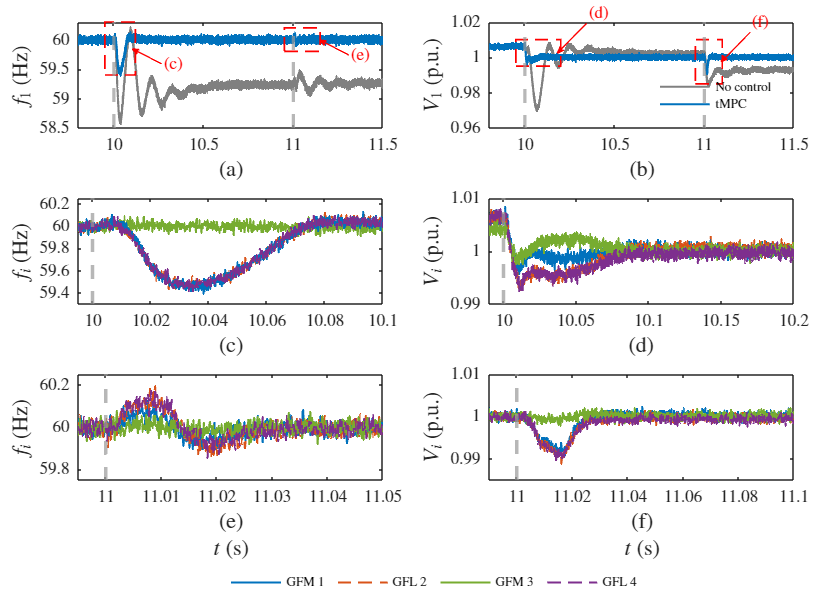

fname=figure_dir+"tmpc.pdf";
exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','none');

fig5=fig; ax5=ax;

### 2.2.2 Figure 6: comparison of the five controllers

Fsize     = 13;
Fsize_xy  = 10;
Fsize_lgd = 8;
Fsize_ann = 10;
Lwidth    = 2;

% Transient markers
clr_trs = [0.6,0.6,0.6];
sty_trs = '--';
lw_trs  = 2;

trng  = [max(t(1),Ttrs(1)-0.2),min(t(end),Ttrs(2)+0.5)];
trng1 = Ttrs(1)+[-0.02,0.2];
trng2 = Ttrs(2)+[-0.02,0.2];

% Controller order: tMPC, PI, RL, Koopman, SINDYc
colors = [0.000 0.447 0.741;
          0.850 0.325 0.098;
          0.466 0.674 0.188;
          0.494 0.184 0.556;
          0.929 0.694 0.125];

styles = {'-', '--', '-.', ':', '-.'};
names  = {'tMPC', 'PI', 'RL', 'Koopman', 'SINDYc'};

lineProps = [num2cell(colors,2), styles(:)];
zoomColumns=[1,2]; % tMPC and PI in the four zoom panels.
koopmanColumn=4;
f=squeeze(f_all(:,indy,2:6));
V=squeeze(V_all(:,indy,2:6));

fig=figure('Name','Controller comparison','Units','inches', ...
    'Position',[1,1,6,7],'Color','w');

tl = tiledlayout(fig,4,2, ...
    'TileSpacing', 'compact', ...
    'Padding', 'compact');

ax = gobjects(6,1);

Fig. 6(a) Frequency overview

ax(1) = nexttile(tl,1,[1,2]);

ind=t>=trng(1) & t<=trng(2);

hA = plot(ax(1),t(ind),f(ind,:), ...
    'LineWidth',Lwidth);
set(hA,{'Color','LineStyle'},lineProps);
uistack(hA(koopmanColumn),'bottom');

xlim(ax(1),trng);
ylim(ax(1),60+[-5, 1]);

limitsA = axis(ax(1));
hTrsA = xline(ax(1),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(1),limitsA);

ylabel(ax(1),sprintf('$f_{%d}$ (Hz)',indy), ...
    'Interpreter','latex','FontSize',Fsize);

xlabel(ax(1),'(a)', ...
    'Interpreter','latex','FontSize',Fsize);

lgd = legend(ax(1),[hA(:)],names, ...
    'Interpreter','latex', ...
    'FontSize',Fsize_lgd, ...
    'Orientation','horizontal', ...
    'NumColumns',5, ...
    'Box','off', ...
    'Color','none', ...
    'AutoUpdate','off');
lgd.Layout.Tile='north';

Fig. 6(b) Voltage overview

ax(2) = nexttile(tl,3,[1,2]);

ind=t>=trng(1) & t<=trng(2);

hB = plot(ax(2),t(ind),V(ind,:), ...
    'LineWidth',Lwidth);
set(hB,{'Color','LineStyle'},lineProps);
uistack(hB(koopmanColumn),'bottom');

xlim(ax(2),trng);
ylim(ax(2),1+[-0.04, 0.02]);

limitsB = axis(ax(2));
hTrsB = xline(ax(2),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(2),limitsB);

ylabel(ax(2),sprintf('$V_{%d}$ (p.u.)',indy), ...
    'Interpreter','latex','FontSize',Fsize);

xlabel(ax(2),{'(b)','$t$ (s)'}, ...
    'Interpreter','latex','FontSize',Fsize);

Fig. 6(c) Frequency after the active-power step

ax(3) = nexttile(tl,5);

ind=t>=trng1(1) & t<=trng1(2);

frng=fbase+[-2,0.4];
hC = plot(ax(3),t(ind),f(ind,zoomColumns), ...
    'LineWidth',Lwidth);
set(hC,{'Color','LineStyle'},lineProps(zoomColumns,:));

xlim(ax(3),trng1);

hTrsC = xline(ax(3),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(3),[trng1,frng]);

ylabel(ax(3),sprintf('$f_{%d}$ (Hz)',indy), ...
    'Interpreter','latex','FontSize',Fsize);

xlabel(ax(3),'(c)', ...
    'Interpreter','latex','FontSize',Fsize);

Fig. 6(d) Frequency after the reactive-power step

ax(4) = nexttile(tl,6);

ind=t>=trng2(1) & t<=trng2(2);

hD = plot(ax(4),t(ind),f(ind,zoomColumns), ...
    'LineWidth',Lwidth);
set(hD,{'Color','LineStyle'},lineProps(zoomColumns,:));

xlim(ax(4),trng2);

hTrsD = xline(ax(4),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(4),[trng2,frng]);

xlabel(ax(4),'(d)', ...
    'Interpreter','latex','FontSize',Fsize);

ax(4).YTickLabel = [];

Fig. 6(e) Voltage after the active-power step

ax(5) = nexttile(tl,7);

ind=t>=trng1(1) & t<=trng1(2);
Vrng=[0.975, 1.02];
hE = plot(ax(5),t(ind),V(ind,zoomColumns), ...
    'LineWidth',Lwidth);
set(hE,{'Color','LineStyle'},lineProps(zoomColumns,:));

xlim(ax(5),trng1);

hTrsE = xline(ax(5),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(5),[trng1,Vrng]);

ylabel(ax(5),sprintf('$V_{%d}$ (p.u.)',indy), ...
    'Interpreter','latex','FontSize',Fsize);

xlabel(ax(5),{'(e)','$t$ (s)'}, ...
    'Interpreter','latex','FontSize',Fsize);

Fig. 6(f) Voltage after the reactive-power step

ax(6) = nexttile(tl,8);

ind=t>=trng2(1) & t<=trng2(2);

hF = plot(ax(6),t(ind),V(ind,zoomColumns), ...
    'LineWidth',Lwidth);
set(hF,{'Color','LineStyle'},lineProps(zoomColumns,:));

xlim(ax(6),trng2);

hTrsF = xline(ax(6),Ttrs, ...
    'Color',clr_trs,'LineStyle',sty_trs,'LineWidth',lw_trs, ...
    'HandleVisibility','off','Layer','bottom');
axis(ax(6),[trng2,Vrng]);

xlabel(ax(6),{'(f)','$t$ (s)'}, ...
    'Interpreter','latex','FontSize',Fsize);

ax(6).YTickLabel = [];

set(ax, ...
    'Color','none', ...
    'Box','on', ...
    'FontSize',Fsize_xy, ...
    'TickLabelInterpreter','latex', ...
    'SortMethod','childorder');
linkaxes(ax([1,2]),'x');     % (a), (b)
linkaxes(ax([3,5]),'x');     % (c), (e)
linkaxes(ax([4,6]),'x');     % (d), (f)

Export Figure 6

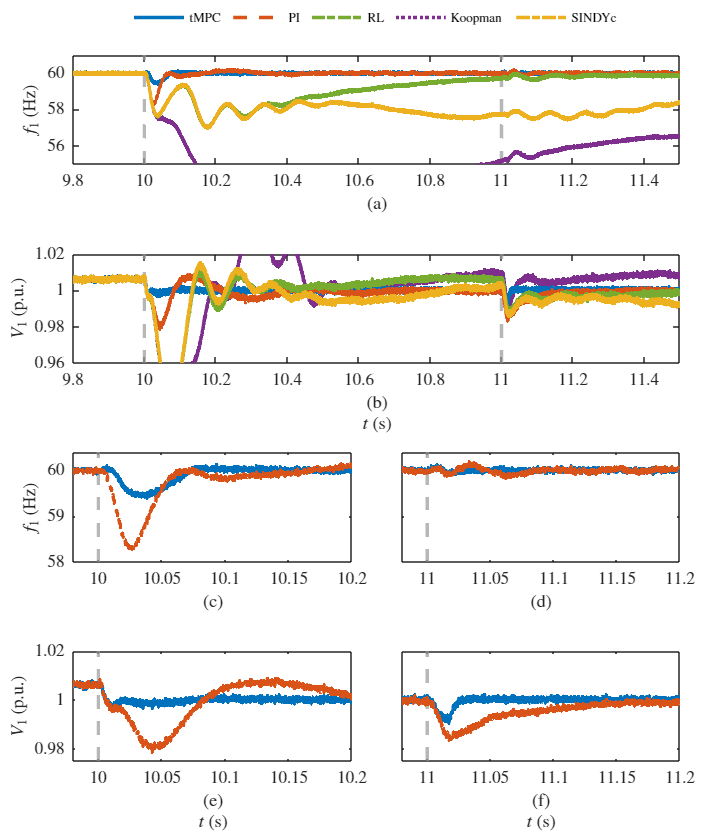

fname=figure_dir+"benchmark.pdf";
exportgraphics(fig,fname,'ContentType','vector','BackgroundColor','none');

fig6=fig; ax6=ax;